# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 05-Dec-2022 16:52:33

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\roadk\Documents\EECE 314\Project\trainingSetup_2022_12_05__16_52_31.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\roadk\Documents\EECE 314\Project\ReorganizedImages","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandScale",[1 2], ...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","gpu",...
    "InitialLearnRate",0.001,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([224 224 3],"Name","input","Mean",trainingSetup.input.Mean)
    convolution2dLayer([3 3],64,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv1_1.Bias,"Weights",trainingSetup.conv1_1.Weights)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],64,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv1_2.Bias,"Weights",trainingSetup.conv1_2.Weights)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv2_1.Bias,"Weights",trainingSetup.conv2_1.Weights)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],128,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv2_2.Bias,"Weights",trainingSetup.conv2_2.Weights)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_1.Bias,"Weights",trainingSetup.conv3_1.Weights)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],256,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_2.Bias,"Weights",trainingSetup.conv3_2.Weights)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],256,"Name","conv3_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_3.Bias,"Weights",trainingSetup.conv3_3.Weights)
    reluLayer("Name","relu3_3")
    convolution2dLayer([3 3],256,"Name","conv3_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_4.Bias,"Weights",trainingSetup.conv3_4.Weights)
    reluLayer("Name","relu3_4")
    maxPooling2dLayer([2 2],"Name","pool3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_1.Bias,"Weights",trainingSetup.conv4_1.Weights)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],512,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_2.Bias,"Weights",trainingSetup.conv4_2.Weights)
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 3],512,"Name","conv4_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_3.Bias,"Weights",trainingSetup.conv4_3.Weights)
    reluLayer("Name","relu4_3")
    convolution2dLayer([3 3],512,"Name","conv4_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_4.Bias,"Weights",trainingSetup.conv4_4.Weights)
    reluLayer("Name","relu4_4")
    maxPooling2dLayer([2 2],"Name","pool4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_1.Bias,"Weights",trainingSetup.conv5_1.Weights)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],512,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_2.Bias,"Weights",trainingSetup.conv5_2.Weights)
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 3],512,"Name","conv5_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_3.Bias,"Weights",trainingSetup.conv5_3.Weights)
    reluLayer("Name","relu5_3")
    convolution2dLayer([3 3],512,"Name","conv5_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_4.Bias,"Weights",trainingSetup.conv5_4.Weights)
    reluLayer("Name","relu5_4")
    maxPooling2dLayer([2 2],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","WeightL2Factor",0,"Bias",trainingSetup.fc6.Bias,"Weights",trainingSetup.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","WeightL2Factor",0,"Bias",trainingSetup.fc7.Bias,"Weights",trainingSetup.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(7,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:43 |        4.69% |       66.94% |       3.8640 |       4.0639 |          0.0010 |


|       1 |           5 |       00:05:01 |       21.88% |       63.42% |       2.4603 |       1.4928 |          0.0010 |


|       1 |          10 |       00:06:18 |       67.19% |       10.95% |       3.1638 |       2.4167 |          0.0010 |


|       1 |          15 |       00:07:33 |       67.19% |       66.94% |       1.4438 |       1.3467 |          0.0010 |


|       1 |          20 |       00:09:06 |       56.25% |       36.32% |       1.3771 |       1.6585 |          0.0010 |


|       1 |          25 |       00:10:37 |       67.19% |       66.94% |       1.0539 |       1.1377 |          0.0010 |


|       1 |          30 |       00:11:56 |       73.44% |       66.94% |       1.0804 |       1.0927 |          0.0010 |


|       1 |          35 |       00:13:20 |       51.56% |       66.91% |       1.0808 |       1.1826 |          0.0010 |


|       1 |          40 |       00:14:48 |       70.31% |       66.94% |       0.9448 |       1.1486 |          0.0010 |


|       1 |          45 |       00:16:07 |       68.75% |       66.94% |       0.7722 |       1.0931 |          0.0010 |


|       1 |          50 |       00:17:37 |       62.50% |       66.94% |       1.0089 |       1.0733 |          0.0010 |


|       1 |          55 |       00:18:55 |       65.63% |       51.63% |       0.9083 |       1.2301 |          0.0010 |


|       1 |          60 |       00:20:20 |       53.13% |       61.42% |       1.2358 |       1.2091 |          0.0010 |


|       1 |          65 |       00:21:38 |       64.06% |       58.95% |       1.3633 |       1.2388 |          0.0010 |


|       1 |          70 |       00:23:32 |       64.06% |       66.94% |       1.1323 |       1.0270 |          0.0010 |


|       1 |          75 |       00:24:50 |       54.69% |       44.74% |       1.2755 |       1.2765 |          0.0010 |


|       1 |          80 |       00:26:07 |       73.44% |       66.98% |       0.8529 |       1.0297 |          0.0010 |


|       1 |          85 |       00:27:24 |       71.88% |       60.19% |       0.7253 |       1.2065 |          0.0010 |


|       1 |          90 |       00:32:50 |       53.13% |       66.94% |       1.1930 |       1.0698 |          0.0010 |


|       1 |          95 |       00:39:26 |       60.94% |       67.04% |       1.0273 |       1.1149 |          0.0010 |


|       1 |         100 |       00:40:44 |       73.44% |       65.88% |       0.7645 |       1.0132 |          0.0010 |


|       1 |         105 |       00:42:06 |       70.31% |       66.91% |       0.7781 |       1.0168 |          0.0010 |


|       2 |         110 |       00:43:30 |       70.31% |       61.88% |       0.9892 |       1.0909 |          0.0010 |


|       2 |         115 |       00:44:53 |       59.38% |       67.68% |       0.9559 |       1.0050 |          0.0010 |


|       2 |         120 |       00:46:12 |       70.31% |       67.01% |       0.8900 |       1.0581 |          0.0010 |


|       2 |         125 |       00:47:38 |       51.56% |       67.64% |       1.4682 |       0.9698 |          0.0010 |


|       2 |         130 |       00:48:57 |       73.44% |       64.81% |       0.8944 |       1.0561 |          0.0010 |


|       2 |         135 |       00:50:17 |       73.44% |       67.34% |       0.7978 |       1.0079 |          0.0010 |


|       2 |         140 |       00:51:42 |       48.44% |       66.94% |       1.2426 |       1.0555 |          0.0010 |


|       2 |         145 |       00:53:07 |       71.88% |       66.94% |       0.8356 |       1.0501 |          0.0010 |


|       2 |         150 |       00:54:24 |       68.75% |       64.71% |       0.9378 |       1.0840 |          0.0010 |


|       2 |         155 |       00:59:23 |       73.44% |       66.94% |       0.7510 |       0.9981 |          0.0010 |


|       2 |         160 |       01:00:46 |       67.19% |       67.44% |       0.9693 |       1.0633 |          0.0010 |


|       2 |         165 |       01:03:16 |       78.13% |       67.11% |       0.6128 |       0.9950 |          0.0010 |


|       2 |         170 |       01:04:53 |       68.75% |       53.76% |       0.8355 |       1.1355 |          0.0010 |


|       2 |         175 |       01:06:11 |       73.44% |       67.81% |       0.7001 |       0.9762 |          0.0010 |


|       2 |         180 |       01:07:31 |       67.19% |       67.21% |       0.7953 |       1.0240 |          0.0010 |


|       2 |         185 |       01:08:52 |       70.31% |       67.28% |       0.8501 |       0.9757 |          0.0010 |


|       2 |         190 |       01:10:04 |       75.00% |       62.62% |       0.7161 |       1.0309 |          0.0010 |


|       2 |         195 |       01:11:25 |       64.06% |       57.89% |       0.9739 |       1.0521 |          0.0010 |


|       2 |         200 |       01:12:43 |       70.31% |       67.28% |       0.8826 |       0.9183 |          0.0010 |


|       2 |         205 |       01:14:07 |       62.50% |       67.08% |       0.9405 |       0.9490 |          0.0010 |


|       2 |         210 |       01:15:29 |       68.75% |       66.81% |       0.9614 |       0.9872 |          0.0010 |


|       2 |         215 |       01:16:51 |       70.31% |       66.34% |       0.9054 |       0.9495 |          0.0010 |


|       3 |         220 |       01:18:16 |       67.19% |       68.28% |       0.7889 |       0.8934 |          0.0010 |


|       3 |         225 |       01:19:34 |       68.75% |       66.81% |       0.8163 |       0.9675 |          0.0010 |


|       3 |         230 |       01:20:58 |       65.63% |       60.05% |       0.9613 |       1.0222 |          0.0010 |


|       3 |         235 |       01:23:07 |       70.31% |       69.04% |       0.6943 |       0.8858 |          0.0010 |


|       3 |         240 |       01:24:33 |       70.31% |       65.15% |       0.7956 |       0.9652 |          0.0010 |


|       3 |         245 |       01:25:55 |       67.19% |       68.77% |       0.7219 |       0.8729 |          0.0010 |


|       3 |         250 |       01:27:20 |       79.69% |       68.77% |       0.6045 |       0.8709 |          0.0010 |


|       3 |         255 |       01:28:58 |       65.63% |       68.94% |       0.9109 |       0.8505 |          0.0010 |


|       3 |         260 |       01:30:17 |       68.75% |       67.04% |       0.8266 |       0.9230 |          0.0010 |


|       3 |         265 |       01:31:39 |       62.50% |       62.05% |       1.0395 |       0.9930 |          0.0010 |


|       3 |         270 |       01:33:04 |       67.19% |       68.58% |       0.9213 |       0.9755 |          0.0010 |


|       3 |         275 |       01:34:23 |       65.63% |       67.64% |       1.1548 |       0.8984 |          0.0010 |


|       3 |         280 |       01:35:40 |       75.00% |       65.25% |       0.7399 |       0.9751 |          0.0010 |


|       3 |         285 |       01:37:07 |       70.31% |       67.64% |       0.7302 |       0.9397 |          0.0010 |


|       3 |         290 |       01:38:25 |       76.56% |       69.51% |       0.6504 |       0.8840 |          0.0010 |


|       3 |         295 |       01:39:49 |       78.13% |       69.71% |       0.5081 |       0.8555 |          0.0010 |


|       3 |         300 |       01:41:10 |       71.88% |       69.47% |       0.6682 |       0.8578 |          0.0010 |


|       3 |         305 |       01:42:48 |       76.56% |       69.81% |       0.6656 |       0.8709 |          0.0010 |


|       3 |         310 |       01:44:21 |       79.69% |       68.84% |       0.6608 |       0.8609 |          0.0010 |


|       3 |         315 |       01:46:11 |       76.56% |       70.14% |       0.6203 |       0.8365 |          0.0010 |


|       3 |         320 |       01:47:32 |       67.19% |       68.04% |       0.8411 |       0.8670 |          0.0010 |


|       3 |         325 |       01:48:57 |       62.50% |       70.01% |       0.9464 |       0.8706 |          0.0010 |


|       4 |         330 |       01:50:16 |       79.69% |       70.21% |       0.5675 |       0.8354 |          0.0010 |


|       4 |         335 |       01:51:29 |       81.25% |       70.54% |       0.6688 |       0.8525 |          0.0010 |


|       4 |         340 |       01:52:47 |       76.56% |       67.08% |       0.6571 |       0.9325 |          0.0010 |


|       4 |         345 |       01:54:14 |       75.00% |       70.81% |       0.6518 |       0.8919 |          0.0010 |


|       4 |         350 |       01:55:34 |       70.31% |       67.11% |       0.7796 |       0.9094 |          0.0010 |


|       4 |         355 |       01:56:47 |       70.31% |       69.54% |       0.9259 |       0.8453 |          0.0010 |


|       4 |         360 |       01:58:12 |       81.25% |       62.78% |       0.6625 |       0.9908 |          0.0010 |


|       4 |         365 |       01:59:27 |       70.31% |       69.67% |       0.8150 |       0.8649 |          0.0010 |


|       4 |         370 |       02:00:46 |       65.63% |       70.14% |       0.8037 |       0.8745 |          0.0010 |


|       4 |         375 |       02:02:28 |       75.00% |       68.94% |       0.6528 |       0.8651 |          0.0010 |


|       4 |         380 |       02:03:49 |       79.69% |       71.04% |       0.6129 |       0.8338 |          0.0010 |


|       4 |         385 |       02:05:14 |       71.88% |       69.01% |       0.6937 |       0.8451 |          0.0010 |


|       4 |         390 |       02:06:55 |       75.00% |       70.67% |       0.6845 |       0.8166 |          0.0010 |


|       4 |         395 |       02:08:10 |       75.00% |       68.74% |       0.6840 |       0.8860 |          0.0010 |


|       4 |         400 |       02:09:27 |       78.13% |       69.24% |       0.6322 |       0.8386 |          0.0010 |


|       4 |         405 |       02:10:44 |       70.31% |       71.01% |       0.6840 |       0.8190 |          0.0010 |


|       4 |         410 |       02:11:59 |       71.88% |       71.21% |       0.7207 |       0.8244 |          0.0010 |


|       4 |         415 |       02:13:23 |       78.13% |       70.54% |       0.5472 |       0.8251 |          0.0010 |


|       4 |         420 |       02:14:54 |       64.06% |       71.84% |       1.1023 |       0.8286 |          0.0010 |


|       4 |         425 |       02:16:10 |       82.81% |       65.68% |       0.6566 |       0.9362 |          0.0010 |


|       4 |         430 |       02:17:27 |       67.19% |       70.14% |       0.8766 |       0.8238 |          0.0010 |


|       4 |         435 |       02:18:51 |       73.44% |       71.14% |       0.7349 |       0.8007 |          0.0010 |


|       5 |         440 |       02:20:10 |       73.44% |       71.01% |       0.6177 |       0.8249 |          0.0010 |


|       5 |         445 |       02:21:28 |       71.88% |       70.17% |       0.7679 |       0.8654 |          0.0010 |


|       5 |         450 |       02:22:35 |       81.25% |       66.11% |       0.5359 |       0.8666 |          0.0010 |


|       5 |         455 |       02:23:42 |       81.25% |       69.77% |       0.4182 |       0.8606 |          0.0010 |


|       5 |         460 |       02:24:52 |       65.63% |       67.84% |       0.8410 |       0.8900 |          0.0010 |


|       5 |         465 |       02:26:01 |       71.88% |       71.54% |       0.6930 |       0.8224 |          0.0010 |


|       5 |         470 |       02:27:06 |       78.13% |       70.71% |       0.6029 |       0.7943 |          0.0010 |


|       5 |         475 |       02:28:13 |       78.13% |       70.47% |       0.7337 |       0.8422 |          0.0010 |


|       5 |         480 |       02:29:21 |       67.19% |       71.17% |       0.8101 |       0.7983 |          0.0010 |


|       5 |         485 |       02:30:27 |       78.13% |       71.87% |       0.5807 |       0.7965 |          0.0010 |


|       5 |         490 |       02:31:33 |       70.31% |       70.31% |       0.6851 |       0.8245 |          0.0010 |


|       5 |         495 |       02:32:41 |       81.25% |       72.57% |       0.7834 |       0.7734 |          0.0010 |


|       5 |         500 |       02:33:49 |       67.19% |       71.27% |       0.8993 |       0.8227 |          0.0010 |


|       5 |         505 |       02:34:56 |       78.13% |       70.67% |       0.7336 |       0.7990 |          0.0010 |


|       5 |         510 |       02:36:02 |       68.75% |       71.37% |       0.7680 |       0.7889 |          0.0010 |


|       5 |         515 |       02:37:09 |       59.38% |       62.52% |       0.7975 |       0.9022 |          0.0010 |


|       5 |         520 |       02:38:13 |       76.56% |       70.97% |       0.7242 |       0.8073 |          0.0010 |


|       5 |         525 |       02:39:23 |       70.31% |       65.21% |       0.7712 |       0.8956 |          0.0010 |


|       5 |         530 |       02:40:29 |       78.13% |       71.70% |       0.7312 |       0.7977 |          0.0010 |


|       5 |         535 |       02:41:33 |       75.00% |       70.21% |       0.6660 |       0.8391 |          0.0010 |


|       5 |         540 |       02:42:39 |       78.13% |       69.94% |       0.8162 |       0.8562 |          0.0010 |


|       5 |         545 |       02:43:54 |       85.94% |       70.24% |       0.5108 |       0.8113 |          0.0010 |


|       6 |         550 |       02:45:03 |       73.44% |       69.97% |       0.6757 |       0.8355 |          0.0010 |


|       6 |         555 |       02:46:08 |       76.56% |       70.84% |       0.6109 |       0.8349 |          0.0010 |


|       6 |         560 |       02:47:13 |       82.81% |       74.17% |       0.5713 |       0.7410 |          0.0010 |


|       6 |         565 |       02:48:34 |       76.56% |       73.77% |       0.6722 |       0.7621 |          0.0010 |


|       6 |         570 |       02:50:05 |       60.94% |       71.60% |       0.7647 |       0.7746 |          0.0010 |


|       6 |         575 |       02:51:31 |       89.06% |       71.27% |       0.4291 |       0.7870 |          0.0010 |


|       6 |         580 |       02:53:03 |       65.63% |       71.50% |       0.7956 |       0.7832 |          0.0010 |


|       6 |         585 |       02:54:20 |       73.44% |       71.94% |       0.6965 |       0.7723 |          0.0010 |


|       6 |         590 |       02:55:40 |       73.44% |       73.00% |       0.7226 |       0.7735 |          0.0010 |


|       6 |         595 |       02:57:17 |       68.75% |       72.74% |       0.6628 |       0.7605 |          0.0010 |


|       6 |         600 |       02:59:16 |       68.75% |       69.71% |       0.6109 |       0.8207 |          0.0010 |


|       6 |         605 |       03:02:20 |       79.69% |       72.27% |       0.5426 |       0.7816 |          0.0010 |


|       6 |         610 |       03:03:56 |       70.31% |       71.77% |       0.7660 |       0.7858 |          0.0010 |


|       6 |         615 |       03:05:36 |       75.00% |       71.27% |       0.6004 |       0.8024 |          0.0010 |


|       6 |         620 |       03:06:57 |       73.44% |       71.97% |       0.6204 |       0.7821 |          0.0010 |


|       6 |         625 |       03:08:41 |       79.69% |       72.50% |       0.5019 |       0.7645 |          0.0010 |


|       6 |         630 |       03:10:12 |       84.38% |       72.70% |       0.5085 |       0.7462 |          0.0010 |


|       6 |         635 |       03:11:28 |       62.50% |       73.04% |       0.9317 |       0.7737 |          0.0010 |


|       6 |         640 |       03:12:42 |       71.88% |       73.20% |       0.6445 |       0.7545 |          0.0010 |


|       6 |         645 |       03:13:59 |       76.56% |       73.74% |       0.6014 |       0.7410 |          0.0010 |


|       6 |         650 |       03:15:30 |       73.44% |       72.50% |       0.6952 |       0.7708 |          0.0010 |


|       7 |         655 |       03:16:50 |       81.25% |       71.57% |       0.6065 |       0.7906 |          0.0010 |


|       7 |         660 |       03:18:04 |       78.13% |       70.41% |       0.6736 |       0.8316 |          0.0010 |


|       7 |         665 |       03:20:16 |       65.63% |       68.01% |       0.8538 |       0.8841 |          0.0010 |


|       7 |         670 |       03:21:44 |       65.63% |       70.21% |       0.8468 |       0.8209 |          0.0010 |


|       7 |         675 |       03:23:08 |       76.56% |       73.04% |       0.6074 |       0.7514 |          0.0010 |


|       7 |         680 |       03:24:29 |       76.56% |       66.21% |       0.6164 |       0.8802 |          0.0010 |


|       7 |         685 |       03:25:45 |       76.56% |       73.54% |       0.5679 |       0.7232 |          0.0010 |


|       7 |         690 |       03:27:03 |       65.63% |       72.34% |       0.8053 |       0.7790 |          0.0010 |


|       7 |         695 |       03:28:23 |       78.13% |       68.31% |       0.5531 |       0.8316 |          0.0010 |


|       7 |         700 |       03:31:00 |       81.25% |       73.70% |       0.5572 |       0.7456 |          0.0010 |


|       7 |         705 |       03:32:22 |       87.50% |       71.57% |       0.5220 |       0.7887 |          0.0010 |


|       7 |         710 |       03:33:46 |       64.06% |       72.14% |       0.9778 |       0.7711 |          0.0010 |


|       7 |         715 |       03:35:19 |       70.31% |       58.89% |       0.7049 |       0.9526 |          0.0010 |


|       7 |         720 |       03:37:20 |       82.81% |       74.13% |       0.6502 |       0.7364 |          0.0010 |


|       7 |         725 |       03:38:45 |       78.13% |       73.37% |       0.6300 |       0.7653 |          0.0010 |


|       7 |         730 |       03:40:06 |       73.44% |       73.30% |       0.5445 |       0.7350 |          0.0010 |


|       7 |         735 |       03:41:23 |       79.69% |       72.70% |       0.5877 |       0.7406 |          0.0010 |


|       7 |         740 |       03:42:42 |       65.63% |       73.10% |       0.8214 |       0.7565 |          0.0010 |


|       7 |         745 |       03:43:59 |       78.13% |       71.87% |       0.5594 |       0.7879 |          0.0010 |


|       7 |         750 |       03:45:34 |       82.81% |       71.70% |       0.5161 |       0.7802 |          0.0010 |


|       7 |         755 |       03:47:15 |       78.13% |       73.47% |       0.5566 |       0.7238 |          0.0010 |


|       7 |         760 |       03:48:58 |       68.75% |       72.00% |       0.7396 |       0.8066 |          0.0010 |


|       8 |         765 |       03:50:20 |       73.44% |       73.07% |       0.8471 |       0.7743 |          0.0010 |


|       8 |         770 |       03:52:29 |       71.88% |       71.84% |       0.7593 |       0.8106 |          0.0010 |


|       8 |         775 |       03:53:48 |       81.25% |       71.01% |       0.5660 |       0.7893 |          0.0010 |


|       8 |         780 |       03:55:06 |       76.56% |       73.50% |       0.6147 |       0.7417 |          0.0010 |


|       8 |         785 |       03:57:02 |       68.75% |       73.04% |       0.7862 |       0.7375 |          0.0010 |


|       8 |         790 |       03:58:18 |       75.00% |       72.84% |       0.6268 |       0.7420 |          0.0010 |


|       8 |         795 |       03:59:38 |       78.13% |       74.20% |       0.5885 |       0.7299 |          0.0010 |


|       8 |         800 |       04:00:52 |       89.06% |       66.84% |       0.3862 |       0.8061 |          0.0010 |


|       8 |         805 |       04:02:26 |       68.75% |       68.61% |       0.7373 |       0.8094 |          0.0010 |


|       8 |         810 |       04:03:55 |       73.44% |       74.60% |       0.8038 |       0.7080 |          0.0010 |


|       8 |         815 |       04:05:12 |       81.25% |       59.49% |       0.5087 |       0.8762 |          0.0010 |


|       8 |         820 |       04:06:31 |       75.00% |       73.70% |       0.6337 |       0.7435 |          0.0010 |


|       8 |         825 |       04:07:59 |       82.81% |       71.37% |       0.5551 |       0.7847 |          0.0010 |


|       8 |         830 |       04:09:16 |       76.56% |       73.07% |       0.5228 |       0.7918 |          0.0010 |


|       8 |         835 |       04:10:49 |       79.69% |       68.81% |       0.6453 |       0.8040 |          0.0010 |


|       8 |         840 |       04:12:09 |       85.94% |       74.33% |       0.4934 |       0.7132 |          0.0010 |


|       8 |         845 |       04:13:35 |       81.25% |       73.44% |       0.4722 |       0.7251 |          0.0010 |


|       8 |         850 |       04:14:54 |       81.25% |       67.34% |       0.6052 |       0.8243 |          0.0010 |


|       8 |         855 |       04:16:14 |       75.00% |       71.30% |       0.6238 |       0.7607 |          0.0010 |


|       8 |         860 |       04:17:28 |       82.81% |       69.71% |       0.4381 |       0.7718 |          0.0010 |


|       8 |         865 |       04:18:50 |       78.13% |       74.33% |       0.7411 |       0.7079 |          0.0010 |


|       8 |         870 |       04:20:11 |       79.69% |       66.25% |       0.5583 |       0.8270 |          0.0010 |


|       9 |         875 |       04:21:33 |       78.13% |       74.87% |       0.5880 |       0.7020 |          0.0010 |


|       9 |         880 |       04:23:18 |       85.94% |       57.36% |       0.4267 |       1.0034 |          0.0010 |


|       9 |         885 |       04:24:40 |       81.25% |       74.60% |       0.5896 |       0.7036 |          0.0010 |


|       9 |         890 |       04:25:53 |       78.13% |       75.30% |       0.6429 |       0.7027 |          0.0010 |


|       9 |         895 |       04:27:31 |       76.56% |       63.02% |       0.6159 |       0.8862 |          0.0010 |


|       9 |         900 |       04:28:56 |       71.88% |       73.37% |       0.6116 |       0.7328 |          0.0010 |


|       9 |         905 |       04:30:05 |       75.00% |       71.27% |       0.6976 |       0.7657 |          0.0010 |


|       9 |         910 |       04:31:12 |       81.25% |       74.60% |       0.5050 |       0.7143 |          0.0010 |


|       9 |         915 |       04:32:23 |       78.13% |       74.23% |       0.6401 |       0.7054 |          0.0010 |


|       9 |         920 |       04:33:30 |       79.69% |       69.37% |       0.6364 |       0.8148 |          0.0010 |


|       9 |         925 |       04:34:39 |       73.44% |       74.03% |       0.7102 |       0.7253 |          0.0010 |


|       9 |         930 |       04:35:49 |       71.88% |       69.14% |       0.5762 |       0.8310 |          0.0010 |


|       9 |         935 |       04:36:53 |       73.44% |       72.57% |       0.6762 |       0.7701 |          0.0010 |


|       9 |         940 |       04:38:01 |       71.88% |       68.08% |       0.5902 |       0.8348 |          0.0010 |


|       9 |         945 |       04:39:08 |       71.88% |       74.17% |       0.6987 |       0.7333 |          0.0010 |


|       9 |         950 |       04:40:13 |       87.50% |       72.47% |       0.3576 |       0.7877 |          0.0010 |


|       9 |         955 |       04:41:21 |       75.00% |       71.40% |       0.6532 |       0.7771 |          0.0010 |


|       9 |         960 |       04:42:30 |       78.13% |       74.10% |       0.5920 |       0.7194 |          0.0010 |


|       9 |         965 |       04:43:35 |       73.44% |       68.54% |       0.5917 |       0.7831 |          0.0010 |


|       9 |         970 |       04:44:45 |       75.00% |       74.73% |       0.7336 |       0.6948 |          0.0010 |


|       9 |         975 |       04:45:52 |       85.94% |       75.33% |       0.5024 |       0.7030 |          0.0010 |


|       9 |         980 |       04:47:02 |       78.13% |       74.93% |       0.5633 |       0.7115 |          0.0010 |


|      10 |         985 |       04:48:09 |       75.00% |       74.30% |       0.6739 |       0.7407 |          0.0010 |


|      10 |         990 |       04:49:17 |       81.25% |       74.70% |       0.4648 |       0.7225 |          0.0010 |


|      10 |         995 |       04:50:25 |       78.13% |       74.43% |       0.6579 |       0.7185 |          0.0010 |


|      10 |        1000 |       04:51:30 |       78.13% |       74.07% |       0.6313 |       0.7189 |          0.0010 |


|      10 |        1005 |       04:52:36 |       71.88% |       75.07% |       0.8858 |       0.6772 |          0.0010 |


|      10 |        1010 |       04:53:42 |       78.13% |       68.24% |       0.6752 |       0.7891 |          0.0010 |


|      10 |        1015 |       04:54:51 |       73.44% |       73.87% |       0.6547 |       0.7333 |          0.0010 |


|      10 |        1020 |       04:55:59 |       75.00% |       70.87% |       0.6828 |       0.8056 |          0.0010 |


|      10 |        1025 |       04:57:04 |       84.38% |       74.37% |       0.4727 |       0.7070 |          0.0010 |


|      10 |        1030 |       04:58:09 |       82.81% |       73.00% |       0.5174 |       0.7364 |          0.0010 |


|      10 |        1035 |       04:59:16 |       82.81% |       72.37% |       0.5070 |       0.7372 |          0.0010 |


|      10 |        1040 |       05:00:20 |       85.94% |       73.24% |       0.4205 |       0.7265 |          0.0010 |


|      10 |        1045 |       05:01:28 |       89.06% |       73.57% |       0.3925 |       0.7311 |          0.0010 |


|      10 |        1050 |       05:02:37 |       78.13% |       71.87% |       0.6880 |       0.7815 |          0.0010 |


|      10 |        1055 |       05:03:44 |       87.50% |       75.10% |       0.4903 |       0.7128 |          0.0010 |


|      10 |        1060 |       05:04:50 |       79.69% |       74.60% |       0.5639 |       0.7068 |          0.0010 |


|      10 |        1065 |       05:05:55 |       85.94% |       75.00% |       0.4080 |       0.7387 |          0.0010 |


|      10 |        1070 |       05:07:03 |       81.25% |       75.20% |       0.4974 |       0.7292 |          0.0010 |


|      10 |        1075 |       05:08:12 |       78.13% |       71.14% |       0.7128 |       0.7865 |          0.0010 |


|      10 |        1080 |       05:09:19 |       84.38% |       74.40% |       0.5269 |       0.7291 |          0.0010 |


|      10 |        1085 |       05:10:23 |       68.75% |       67.21% |       0.7568 |       0.8941 |          0.0010 |


|      10 |        1090 |       05:11:32 |       73.44% |       73.34% |       0.6022 |       0.7197 |          0.0010 |


|      11 |        1095 |       05:12:40 |       68.75% |       68.61% |       0.7398 |       0.7628 |          0.0010 |


|      11 |        1100 |       05:13:47 |       76.56% |       73.37% |       0.5984 |       0.7262 |          0.0010 |


|      11 |        1105 |       05:14:54 |       85.94% |       57.09% |       0.3682 |       0.9212 |          0.0010 |


|      11 |        1110 |       05:16:02 |       73.44% |       72.74% |       0.6352 |       0.7376 |          0.0010 |


|      11 |        1115 |       05:17:10 |       76.56% |       73.74% |       0.5703 |       0.7138 |          0.0010 |


|      11 |        1120 |       05:18:17 |       82.81% |       71.07% |       0.4402 |       0.7269 |          0.0010 |


|      11 |        1125 |       05:19:27 |       79.69% |       71.90% |       0.5786 |       0.7503 |          0.0010 |


|      11 |        1130 |       05:20:36 |       82.81% |       64.68% |       0.4671 |       0.8746 |          0.0010 |


|      11 |        1135 |       05:21:40 |       73.44% |       67.98% |       0.6874 |       0.7679 |          0.0010 |


|      11 |        1140 |       05:22:47 |       79.69% |       73.60% |       0.5052 |       0.7151 |          0.0010 |


|      11 |        1145 |       05:23:56 |       81.25% |       74.20% |       0.5304 |       0.6995 |          0.0010 |


|      11 |        1150 |       05:25:03 |       84.38% |       63.45% |       0.5055 |       0.8179 |          0.0010 |


|      11 |        1155 |       05:26:08 |       73.44% |       75.57% |       0.5991 |       0.6676 |          0.0010 |


|      11 |        1160 |       05:27:14 |       78.13% |       72.87% |       0.5867 |       0.7243 |          0.0010 |


|      11 |        1165 |       05:28:21 |       85.94% |       73.64% |       0.4560 |       0.7004 |          0.0010 |


|      11 |        1170 |       05:29:28 |       76.56% |       75.03% |       0.6410 |       0.7183 |          0.0010 |


|      11 |        1175 |       05:30:36 |       78.13% |       69.41% |       0.5680 |       0.7811 |          0.0010 |


|      11 |        1180 |       05:31:40 |       79.69% |       76.66% |       0.5384 |       0.6775 |          0.0010 |


|      11 |        1185 |       05:32:50 |       76.56% |       75.53% |       0.5559 |       0.7238 |          0.0010 |


|      11 |        1190 |       05:33:56 |       76.56% |       74.70% |       0.6422 |       0.7249 |          0.0010 |


|      11 |        1195 |       05:35:03 |       89.06% |       74.73% |       0.4121 |       0.7116 |          0.0010 |


|      12 |        1200 |       05:36:11 |       87.50% |       69.97% |       0.3830 |       0.7943 |          0.0010 |


|      12 |        1205 |       05:37:16 |       68.75% |       74.63% |       0.6647 |       0.7207 |          0.0010 |


|      12 |        1210 |       05:38:26 |       71.88% |       68.21% |       0.6901 |       0.8259 |          0.0010 |


|      12 |        1215 |       05:39:31 |       84.38% |       75.40% |       0.4349 |       0.6870 |          0.0010 |


|      12 |        1220 |       05:40:40 |       79.69% |       73.27% |       0.5656 |       0.7099 |          0.0010 |


|      12 |        1225 |       05:41:47 |       81.25% |       63.28% |       0.5968 |       0.9256 |          0.0010 |


|      12 |        1230 |       05:42:55 |       76.56% |       74.50% |       0.5808 |       0.6810 |          0.0010 |


|      12 |        1235 |       05:44:00 |       81.25% |       70.44% |       0.5453 |       0.7762 |          0.0010 |


|      12 |        1240 |       05:45:09 |       82.81% |       71.50% |       0.4673 |       0.7666 |          0.0010 |


|      12 |        1245 |       05:46:15 |       82.81% |       73.64% |       0.4466 |       0.7266 |          0.0010 |


|      12 |        1250 |       05:47:21 |       85.94% |       75.63% |       0.5648 |       0.6869 |          0.0010 |


|      12 |        1255 |       05:48:27 |       82.81% |       58.46% |       0.5292 |       0.9137 |          0.0010 |


|      12 |        1260 |       05:49:36 |       76.56% |       73.44% |       0.6544 |       0.7741 |          0.0010 |


|      12 |        1265 |       05:50:44 |       78.13% |       72.14% |       0.5958 |       0.7392 |          0.0010 |


|      12 |        1270 |       05:51:49 |       75.00% |       67.64% |       0.5821 |       0.8024 |          0.0010 |


|      12 |        1275 |       05:52:55 |       68.75% |       73.07% |       0.8243 |       0.7262 |          0.0010 |


|      12 |        1280 |       05:54:00 |       79.69% |       76.13% |       0.5933 |       0.6597 |          0.0010 |


|      12 |        1285 |       05:55:07 |       84.38% |       65.28% |       0.5356 |       0.8252 |          0.0010 |


|      12 |        1290 |       05:56:15 |       82.81% |       75.47% |       0.4287 |       0.7019 |          0.0010 |


|      12 |        1295 |       05:57:22 |       87.50% |       68.18% |       0.3514 |       0.7943 |          0.0010 |


|      12 |        1300 |       05:58:30 |       75.00% |       70.51% |       0.6951 |       0.7570 |          0.0010 |


|      12 |        1305 |       05:59:36 |       84.38% |       72.24% |       0.4321 |       0.7227 |          0.0010 |


|      13 |        1310 |       06:00:45 |       85.94% |       63.72% |       0.3707 |       0.8815 |          0.0010 |


|      13 |        1315 |       06:01:52 |       82.81% |       72.30% |       0.6125 |       0.7164 |          0.0010 |


|      13 |        1320 |       06:03:02 |       71.88% |       74.57% |       0.7160 |       0.7054 |          0.0010 |


|      13 |        1325 |       06:04:11 |       82.81% |       69.21% |       0.4896 |       0.7597 |          0.0010 |


|      13 |        1330 |       06:05:18 |       78.13% |       68.21% |       0.6196 |       0.7794 |          0.0010 |


|      13 |        1335 |       06:06:25 |       84.38% |       72.70% |       0.4079 |       0.7284 |          0.0010 |


|      13 |        1340 |       06:07:37 |       82.81% |       71.34% |       0.3896 |       0.7398 |          0.0010 |


|      13 |        1345 |       06:08:41 |       73.44% |       76.10% |       0.5761 |       0.6581 |          0.0010 |


|      13 |        1350 |       06:09:46 |       76.56% |       70.01% |       0.5517 |       0.7829 |          0.0010 |


|      13 |        1355 |       06:10:56 |       89.06% |       71.67% |       0.4654 |       0.7256 |          0.0010 |


|      13 |        1360 |       06:12:01 |       70.31% |       73.90% |       0.6600 |       0.7055 |          0.0010 |


|      13 |        1365 |       06:13:12 |       82.81% |       59.35% |       0.4802 |       0.9211 |          0.0010 |


|      13 |        1370 |       06:14:20 |       84.38% |       74.30% |       0.4188 |       0.7035 |          0.0010 |


|      13 |        1375 |       06:15:26 |       75.00% |       73.60% |       0.6193 |       0.7460 |          0.0010 |


|      13 |        1380 |       06:16:31 |       78.13% |       74.53% |       0.4893 |       0.7260 |          0.0010 |


|      13 |        1385 |       06:17:39 |       76.56% |       74.97% |       0.5951 |       0.7150 |          0.0010 |


|      13 |        1390 |       06:18:46 |       79.69% |       74.40% |       0.5148 |       0.7270 |          0.0010 |


|      13 |        1395 |       06:19:51 |       79.69% |       64.68% |       0.4379 |       0.8095 |          0.0010 |


|      13 |        1400 |       06:20:58 |       79.69% |       75.73% |       0.5935 |       0.6766 |          0.0010 |


|      13 |        1405 |       06:22:06 |       82.81% |       73.47% |       0.4299 |       0.7298 |          0.0010 |


|      13 |        1410 |       06:23:12 |       79.69% |       69.87% |       0.5028 |       0.7445 |          0.0010 |


|      13 |        1415 |       06:24:20 |       76.56% |       69.01% |       0.4605 |       0.7588 |          0.0010 |


|      14 |        1420 |       06:25:29 |       79.69% |       76.76% |       0.5193 |       0.6592 |          0.0010 |


|      14 |        1425 |       06:26:34 |       79.69% |       71.74% |       0.5049 |       0.7159 |          0.0010 |


|      14 |        1430 |       06:27:43 |       89.06% |       73.20% |       0.3060 |       0.7056 |          0.0010 |


|      14 |        1435 |       06:28:49 |       81.25% |       74.37% |       0.4128 |       0.7215 |          0.0010 |


|      14 |        1440 |       06:29:54 |       82.81% |       67.64% |       0.5787 |       0.7820 |          0.0010 |


|      14 |        1445 |       06:31:03 |       82.81% |       67.64% |       0.6226 |       0.7760 |          0.0010 |


|      14 |        1450 |       06:32:11 |       81.25% |       65.38% |       0.5012 |       0.8456 |          0.0010 |


|      14 |        1455 |       06:33:21 |       71.88% |       70.54% |       0.6898 |       0.7569 |          0.0010 |


|      14 |        1460 |       06:34:31 |       76.56% |       68.94% |       0.6037 |       0.7554 |          0.0010 |


|      14 |        1465 |       06:35:38 |       79.69% |       73.64% |       0.5710 |       0.7070 |          0.0010 |


|      14 |        1470 |       06:36:42 |       81.25% |       74.97% |       0.5063 |       0.6696 |          0.0010 |


|      14 |        1475 |       06:37:50 |       76.56% |       72.00% |       0.6025 |       0.7402 |          0.0010 |


|      14 |        1480 |       06:38:57 |       84.38% |       76.07% |       0.3713 |       0.6829 |          0.0010 |


|      14 |        1485 |       06:40:04 |       65.63% |       70.67% |       0.8168 |       0.7496 |          0.0010 |


|      14 |        1490 |       06:41:12 |       75.00% |       73.64% |       0.6043 |       0.7092 |          0.0010 |


|      14 |        1495 |       06:42:21 |       84.38% |       72.34% |       0.4004 |       0.7348 |          0.0010 |


|      14 |        1500 |       06:43:29 |       76.56% |       71.30% |       0.5891 |       0.7210 |          0.0010 |


|      14 |        1505 |       06:44:36 |       76.56% |       77.03% |       0.4380 |       0.6479 |          0.0010 |


|      14 |        1510 |       06:45:42 |       87.50% |       70.37% |       0.3833 |       0.7257 |          0.0010 |


|      14 |        1515 |       06:46:50 |       71.88% |       69.27% |       0.6892 |       0.7625 |          0.0010 |


|      14 |        1520 |       06:47:55 |       73.44% |       72.77% |       0.5444 |       0.7201 |          0.0010 |


|      14 |        1525 |       06:49:01 |       79.69% |       61.15% |       0.5492 |       0.8503 |          0.0010 |


|      15 |        1530 |       06:50:08 |       85.94% |       75.13% |       0.3920 |       0.6804 |          0.0010 |


|      15 |        1535 |       06:51:16 |       84.38% |       69.84% |       0.5267 |       0.8176 |          0.0010 |


|      15 |        1540 |       06:52:20 |       81.25% |       75.13% |       0.5008 |       0.7027 |          0.0010 |


|      15 |        1545 |       06:53:26 |       78.13% |       75.03% |       0.4824 |       0.7098 |          0.0010 |


|      15 |        1550 |       06:54:33 |       79.69% |       75.03% |       0.5018 |       0.6820 |          0.0010 |


|      15 |        1555 |       06:55:40 |       85.94% |       75.73% |       0.4301 |       0.6543 |          0.0010 |


|      15 |        1560 |       06:56:46 |       76.56% |       77.20% |       0.5241 |       0.6285 |          0.0010 |


|      15 |        1565 |       06:57:53 |       87.50% |       76.00% |       0.3859 |       0.6523 |          0.0010 |


|      15 |        1570 |       06:59:03 |       89.06% |       72.34% |       0.3323 |       0.7089 |          0.0010 |


|      15 |        1575 |       07:00:13 |       85.94% |       73.64% |       0.5527 |       0.6873 |          0.0010 |


|      15 |        1580 |       07:01:21 |       89.06% |       74.07% |       0.4539 |       0.6985 |          0.0010 |


|      15 |        1585 |       07:02:30 |       81.25% |       60.49% |       0.5438 |       0.8534 |          0.0010 |


|      15 |        1590 |       07:03:38 |       76.56% |       72.50% |       0.5745 |       0.7372 |          0.0010 |


|      15 |        1595 |       07:04:45 |       84.38% |       70.54% |       0.4661 |       0.7613 |          0.0010 |


|      15 |        1600 |       07:05:51 |       79.69% |       74.93% |       0.6258 |       0.6629 |          0.0010 |


|      15 |        1605 |       07:06:57 |       70.31% |       74.77% |       0.6771 |       0.6912 |          0.0010 |


|      15 |        1610 |       07:08:02 |       82.81% |       72.04% |       0.4700 |       0.7166 |          0.0010 |


|      15 |        1615 |       07:09:09 |       75.00% |       70.87% |       0.8054 |       0.7269 |          0.0010 |


|      15 |        1620 |       07:10:17 |       82.81% |       72.70% |       0.5372 |       0.7053 |          0.0010 |


|      15 |        1625 |       07:11:21 |       78.13% |       75.77% |       0.5628 |       0.6665 |          0.0010 |


|      15 |        1630 |       07:12:29 |       76.56% |       71.60% |       0.6284 |       0.7007 |          0.0010 |


|      15 |        1635 |       07:13:39 |       87.50% |       74.13% |       0.3801 |       0.6786 |          0.0010 |


|      16 |        1640 |       07:14:44 |       85.94% |       72.87% |       0.3751 |       0.7178 |          0.0010 |


|      16 |        1645 |       07:15:50 |       81.25% |       68.81% |       0.5941 |       0.7701 |          0.0010 |


|      16 |        1650 |       07:16:55 |       82.81% |       74.87% |       0.4454 |       0.6824 |          0.0010 |


|      16 |        1655 |       07:18:01 |       85.94% |       77.43% |       0.4437 |       0.6401 |          0.0010 |


|      16 |        1660 |       07:19:08 |       79.69% |       74.97% |       0.6483 |       0.6865 |          0.0010 |


|      16 |        1665 |       07:20:15 |       73.44% |       77.10% |       0.5612 |       0.6680 |          0.0010 |


|      16 |        1670 |       07:21:21 |       82.81% |       75.90% |       0.4169 |       0.6910 |          0.0010 |


|      16 |        1675 |       07:22:27 |       75.00% |       75.27% |       0.5086 |       0.6753 |          0.0010 |


|      16 |        1680 |       07:23:34 |       81.25% |       76.70% |       0.5570 |       0.6561 |          0.0010 |


|      16 |        1685 |       07:24:42 |       81.25% |       64.01% |       0.4495 |       0.9156 |          0.0010 |


|      16 |        1690 |       07:25:50 |       76.56% |       76.20% |       0.7236 |       0.6643 |          0.0010 |


|      16 |        1695 |       07:26:58 |       79.69% |       66.74% |       0.5797 |       0.7897 |          0.0010 |


|      16 |        1700 |       07:28:04 |       79.69% |       74.37% |       0.5312 |       0.6932 |          0.0010 |


|      16 |        1705 |       07:29:10 |       85.94% |       68.87% |       0.2934 |       0.7923 |          0.0010 |


|      16 |        1710 |       07:30:21 |       85.94% |       76.07% |       0.3802 |       0.6764 |          0.0010 |


|      16 |        1715 |       07:31:26 |       84.38% |       74.43% |       0.4477 |       0.6920 |          0.0010 |


|      16 |        1720 |       07:32:32 |       82.81% |       75.93% |       0.5071 |       0.6721 |          0.0010 |


|      16 |        1725 |       07:33:38 |       79.69% |       74.90% |       0.4426 |       0.6935 |          0.0010 |


|      16 |        1730 |       07:34:46 |       84.38% |       69.91% |       0.4611 |       0.7222 |          0.0010 |


|      16 |        1735 |       07:35:52 |       81.25% |       65.18% |       0.5019 |       0.7964 |          0.0010 |


|      16 |        1740 |       07:36:56 |       78.13% |       76.26% |       0.7077 |       0.6588 |          0.0010 |


|      17 |        1745 |       07:38:07 |       79.69% |       72.04% |       0.6576 |       0.7165 |          0.0010 |


|      17 |        1750 |       07:39:14 |       79.69% |       71.77% |       0.5447 |       0.7036 |          0.0010 |


|      17 |        1755 |       07:40:19 |       78.13% |       71.90% |       0.5304 |       0.7178 |          0.0010 |


|      17 |        1760 |       07:41:27 |       84.38% |       76.90% |       0.3918 |       0.6455 |          0.0010 |


|      17 |        1765 |       07:42:36 |       82.81% |       73.60% |       0.3531 |       0.6983 |          0.0010 |


|      17 |        1770 |       07:43:43 |       85.94% |       74.07% |       0.3651 |       0.6968 |          0.0010 |


|      17 |        1775 |       07:44:48 |       79.69% |       74.53% |       0.4359 |       0.6843 |          0.0010 |


|      17 |        1780 |       07:45:55 |       78.13% |       70.07% |       0.5576 |       0.7753 |          0.0010 |


|      17 |        1785 |       07:47:04 |       71.88% |       76.23% |       0.7911 |       0.7367 |          0.0010 |


|      17 |        1790 |       07:48:13 |       79.69% |       74.27% |       0.5497 |       0.6967 |          0.0010 |


|      17 |        1795 |       07:49:17 |       81.25% |       72.60% |       0.4925 |       0.7396 |          0.0010 |


|      17 |        1800 |       07:50:23 |       89.06% |       65.51% |       0.3626 |       0.8388 |          0.0010 |


|      17 |        1805 |       07:51:32 |       78.13% |       74.27% |       0.5538 |       0.6688 |          0.0010 |


|      17 |        1810 |       07:52:38 |       81.25% |       63.18% |       0.5491 |       0.8421 |          0.0010 |


|      17 |        1815 |       07:53:45 |       68.75% |       76.17% |       0.6511 |       0.6821 |          0.0010 |


|      17 |        1820 |       07:54:52 |       81.25% |       65.08% |       0.4465 |       0.8310 |          0.0010 |


|      17 |        1825 |       07:56:03 |       85.94% |       74.47% |       0.4535 |       0.7033 |          0.0010 |


|      17 |        1830 |       07:57:12 |       89.06% |       76.60% |       0.3748 |       0.6417 |          0.0010 |


|      17 |        1835 |       07:58:18 |       79.69% |       66.54% |       0.4742 |       0.7959 |          0.0010 |


|      17 |        1840 |       07:59:26 |       64.06% |       72.74% |       1.0307 |       0.7030 |          0.0010 |


|      17 |        1845 |       08:00:34 |       90.63% |       70.24% |       0.3161 |       0.7539 |          0.0010 |


|      17 |        1850 |       08:01:40 |       81.25% |       74.87% |       0.5497 |       0.6934 |          0.0010 |


|      18 |        1855 |       08:02:46 |       89.06% |       72.54% |       0.3693 |       0.7322 |          0.0010 |


|      18 |        1860 |       08:03:52 |       82.81% |       77.10% |       0.5647 |       0.6498 |          0.0010 |


|      18 |        1865 |       08:04:59 |       84.38% |       74.43% |       0.3681 |       0.6841 |          0.0010 |


|      18 |        1870 |       08:06:07 |       79.69% |       73.77% |       0.5032 |       0.6951 |          0.0010 |


|      18 |        1875 |       08:07:15 |       79.69% |       67.78% |       0.6255 |       0.8148 |          0.0010 |


|      18 |        1880 |       08:08:22 |       78.13% |       72.47% |       0.6145 |       0.7037 |          0.0010 |


|      18 |        1885 |       08:09:30 |       84.38% |       71.97% |       0.3875 |       0.7423 |          0.0010 |


|      18 |        1890 |       08:10:40 |       82.81% |       67.34% |       0.4524 |       0.8050 |          0.0010 |


|      18 |        1895 |       08:11:47 |       79.69% |       75.87% |       0.5193 |       0.6725 |          0.0010 |


|      18 |        1900 |       08:12:57 |       76.56% |       63.58% |       0.5948 |       0.8294 |          0.0010 |


|      18 |        1905 |       08:14:03 |       81.25% |       71.04% |       0.5888 |       0.7316 |          0.0010 |


|      18 |        1910 |       08:15:09 |       90.63% |       74.20% |       0.3200 |       0.6884 |          0.0010 |


|      18 |        1915 |       08:16:15 |       81.25% |       73.24% |       0.4626 |       0.6929 |          0.0010 |


|      18 |        1920 |       08:17:22 |       84.38% |       74.93% |       0.4744 |       0.6749 |          0.0010 |


|      18 |        1925 |       08:18:30 |       87.50% |       76.60% |       0.4210 |       0.6642 |          0.0010 |


|      18 |        1930 |       08:19:38 |       73.44% |       77.06% |       0.5750 |       0.6831 |          0.0010 |


|      18 |        1935 |       08:20:46 |       75.00% |       75.53% |       0.7239 |       0.7412 |          0.0010 |


|      18 |        1940 |       08:21:52 |       82.81% |       69.34% |       0.4552 |       0.8018 |          0.0010 |


|      18 |        1945 |       08:23:03 |       79.69% |       72.94% |       0.5016 |       0.7446 |          0.0010 |


|      18 |        1950 |       08:24:11 |       79.69% |       76.33% |       0.5484 |       0.6627 |          0.0010 |


|      18 |        1955 |       08:25:12 |       84.38% |       75.50% |       0.5002 |       0.6724 |          0.0010 |


|      18 |        1960 |       08:26:17 |       78.13% |       68.94% |       0.5143 |       0.8093 |          0.0010 |


|      19 |        1965 |       08:27:24 |       90.63% |       75.33% |       0.3510 |       0.6848 |          0.0010 |


|      19 |        1970 |       08:28:32 |       73.44% |       73.60% |       0.5633 |       0.6882 |          0.0010 |


|      19 |        1975 |       08:29:43 |       82.81% |       74.67% |       0.4115 |       0.7174 |          0.0010 |


|      19 |        1980 |       08:30:50 |       84.38% |       72.74% |       0.5114 |       0.7168 |          0.0010 |


|      19 |        1985 |       08:31:58 |       79.69% |       69.91% |       0.4287 |       0.7583 |          0.0010 |


|      19 |        1990 |       08:33:06 |       79.69% |       77.33% |       0.4667 |       0.6524 |          0.0010 |


|      19 |        1995 |       08:34:14 |       78.13% |       74.37% |       0.5269 |       0.6865 |          0.0010 |


|      19 |        2000 |       08:35:21 |       87.50% |       75.97% |       0.4240 |       0.6737 |          0.0010 |


|      19 |        2005 |       08:36:28 |       84.38% |       71.67% |       0.3988 |       0.7046 |          0.0010 |


|      19 |        2010 |       08:37:36 |       87.50% |       74.97% |       0.3621 |       0.6582 |          0.0010 |


|      19 |        2015 |       08:38:47 |       84.38% |       74.33% |       0.4513 |       0.6664 |          0.0010 |


|      19 |        2020 |       08:39:53 |       78.13% |       72.80% |       0.4868 |       0.7316 |          0.0010 |


|      19 |        2025 |       08:40:59 |       78.13% |       76.20% |       0.4717 |       0.6708 |          0.0010 |


|      19 |        2030 |       08:42:07 |       82.81% |       75.33% |       0.3849 |       0.6648 |          0.0010 |


|      19 |        2035 |       08:43:14 |       81.25% |       71.67% |       0.4811 |       0.6933 |          0.0010 |


|      19 |        2040 |       08:44:23 |       84.38% |       73.30% |       0.4981 |       0.7210 |          0.0010 |


|      19 |        2045 |       08:45:32 |       79.69% |       67.78% |       0.4641 |       0.8262 |          0.0010 |


|      19 |        2050 |       08:46:38 |       76.56% |       70.27% |       0.6269 |       0.7439 |          0.0010 |


|      19 |        2055 |       08:47:45 |       73.44% |       65.51% |       0.6673 |       0.8086 |          0.0010 |


|      19 |        2060 |       08:48:53 |       85.94% |       75.37% |       0.3634 |       0.7193 |          0.0010 |


|      19 |        2065 |       08:49:55 |       78.13% |       72.14% |       0.5949 |       0.7361 |          0.0010 |


|      19 |        2070 |       08:51:02 |       87.50% |       71.30% |       0.4245 |       0.7321 |          0.0010 |


|      20 |        2075 |       08:52:10 |       84.38% |       75.73% |       0.4337 |       0.6749 |          0.0010 |


|      20 |        2080 |       08:53:17 |       89.06% |       76.30% |       0.3241 |       0.6341 |          0.0010 |


|      20 |        2085 |       08:54:23 |       84.38% |       73.20% |       0.4809 |       0.7459 |          0.0010 |


|      20 |        2090 |       08:55:29 |       84.38% |       73.70% |       0.3511 |       0.6816 |          0.0010 |


|      20 |        2095 |       08:56:39 |       79.69% |       77.16% |       0.5810 |       0.6448 |          0.0010 |


|      20 |        2100 |       08:57:48 |       84.38% |       77.06% |       0.4196 |       0.6600 |          0.0010 |


|      20 |        2105 |       08:58:56 |       82.81% |       74.43% |       0.4378 |       0.7153 |          0.0010 |


|      20 |        2110 |       09:00:02 |       81.25% |       72.44% |       0.4796 |       0.7175 |          0.0010 |


|      20 |        2115 |       09:01:08 |       85.94% |       77.56% |       0.3353 |       0.6275 |          0.0010 |


|      20 |        2120 |       09:02:14 |       84.38% |       70.07% |       0.4259 |       0.7368 |          0.0010 |


|      20 |        2125 |       09:03:23 |       82.81% |       76.30% |       0.5379 |       0.6626 |          0.0010 |


|      20 |        2130 |       09:04:34 |       81.25% |       75.63% |       0.5505 |       0.6725 |          0.0010 |


|      20 |        2135 |       09:05:40 |       84.38% |       75.47% |       0.3935 |       0.6841 |          0.0010 |


|      20 |        2140 |       09:06:46 |       82.81% |       76.50% |       0.4165 |       0.6684 |          0.0010 |


|      20 |        2145 |       09:07:55 |       85.94% |       72.74% |       0.4679 |       0.7070 |          0.0010 |


|      20 |        2150 |       09:09:03 |       84.38% |       71.30% |       0.3746 |       0.7043 |          0.0010 |


|      20 |        2155 |       09:10:09 |       87.50% |       73.54% |       0.2783 |       0.7031 |          0.0010 |


|      20 |        2160 |       09:11:14 |       87.50% |       76.33% |       0.3140 |       0.6572 |          0.0010 |


|      20 |        2165 |       09:12:23 |       95.31% |       67.94% |       0.3349 |       0.7695 |          0.0010 |


|      20 |        2170 |       09:13:30 |       75.00% |       75.80% |       0.4565 |       0.6555 |          0.0010 |


|      20 |        2175 |       09:14:39 |       95.31% |       75.63% |       0.1967 |       0.6535 |          0.0010 |


|      20 |        2180 |       09:15:47 |       82.81% |       71.21% |       0.4941 |       0.7186 |          0.0010 |


|      21 |        2185 |       09:16:55 |       75.00% |       66.98% |       0.5932 |       0.8034 |          0.0010 |


|      21 |        2190 |       09:18:02 |       87.50% |       72.90% |       0.3545 |       0.7284 |          0.0010 |


|      21 |        2195 |       09:19:07 |       79.69% |       73.44% |       0.5455 |       0.7278 |          0.0010 |


|      21 |        2200 |       09:20:16 |       85.94% |       71.70% |       0.4448 |       0.7226 |          0.0010 |


|      21 |        2205 |       09:21:22 |       87.50% |       75.57% |       0.3772 |       0.6588 |          0.0010 |


|      21 |        2210 |       09:22:30 |       87.50% |       69.84% |       0.2905 |       0.7580 |          0.0010 |


|      21 |        2215 |       09:23:37 |       89.06% |       79.16% |       0.3663 |       0.6013 |          0.0010 |


|      21 |        2220 |       09:24:45 |       81.25% |       74.27% |       0.3644 |       0.6680 |          0.0010 |


|      21 |        2225 |       09:25:54 |       82.81% |       76.66% |       0.4319 |       0.6455 |          0.0010 |


|      21 |        2230 |       09:27:01 |       87.50% |       71.17% |       0.3096 |       0.7135 |          0.0010 |


|      21 |        2235 |       09:28:09 |       85.94% |       73.10% |       0.3961 |       0.6917 |          0.0010 |


|      21 |        2240 |       09:29:22 |       78.13% |       69.71% |       0.4781 |       0.7661 |          0.0010 |


|      21 |        2245 |       09:30:28 |       81.25% |       76.73% |       0.4464 |       0.6442 |          0.0010 |


|      21 |        2250 |       09:31:38 |       90.63% |       73.07% |       0.3237 |       0.7204 |          0.0010 |


|      21 |        2255 |       09:32:52 |       81.25% |       74.47% |       0.3996 |       0.7068 |          0.0010 |


|      21 |        2260 |       09:34:02 |       89.06% |       72.84% |       0.3566 |       0.6896 |          0.0010 |


|      21 |        2265 |       09:35:08 |       81.25% |       67.08% |       0.4624 |       0.8023 |          0.0010 |


|      21 |        2270 |       09:36:16 |       76.56% |       74.20% |       0.4245 |       0.7231 |          0.0010 |


|      21 |        2275 |       09:37:23 |       75.00% |       66.38% |       0.8283 |       0.7805 |          0.0010 |


|      21 |        2280 |       09:38:28 |       90.63% |       74.17% |       0.2843 |       0.7047 |          0.0010 |


|      21 |        2285 |       09:39:33 |       79.69% |       71.94% |       0.5355 |       0.7098 |          0.0010 |


|      22 |        2290 |       09:40:39 |       85.94% |       64.45% |       0.4693 |       0.7997 |          0.0010 |


|      22 |        2295 |       09:41:51 |       90.63% |       74.33% |       0.2741 |       0.6608 |          0.0010 |


|      22 |        2300 |       09:42:59 |       73.44% |       71.74% |       0.6747 |       0.6879 |          0.0010 |


|      22 |        2305 |       09:44:05 |       76.56% |       68.24% |       0.6953 |       0.7631 |          0.0010 |


|      22 |        2310 |       09:45:15 |       84.38% |       71.27% |       0.4337 |       0.7181 |          0.0010 |


|      22 |        2315 |       09:46:22 |       82.81% |       74.37% |       0.4202 |       0.6904 |          0.0010 |


|      22 |        2320 |       09:47:31 |       89.06% |       62.82% |       0.4040 |       0.8224 |          0.0010 |


|      22 |        2325 |       09:48:36 |       89.06% |       71.77% |       0.3963 |       0.6890 |          0.0010 |


|      22 |        2330 |       09:49:42 |       68.75% |       73.60% |       0.6042 |       0.6884 |          0.0010 |


|      22 |        2335 |       09:50:50 |       81.25% |       75.10% |       0.4126 |       0.6494 |          0.0010 |


|      22 |        2340 |       09:51:59 |       90.63% |       64.25% |       0.3108 |       0.8261 |          0.0010 |


|      22 |        2345 |       09:53:07 |       82.81% |       74.67% |       0.5091 |       0.6520 |          0.0010 |


|      22 |        2350 |       09:54:16 |       78.13% |       74.83% |       0.5006 |       0.6809 |          0.0010 |


|      22 |        2355 |       09:55:22 |       89.06% |       76.50% |       0.2649 |       0.6602 |          0.0010 |


|      22 |        2360 |       09:56:28 |       84.38% |       72.27% |       0.4127 |       0.7117 |          0.0010 |


|      22 |        2365 |       09:57:35 |       87.50% |       76.50% |       0.3323 |       0.6753 |          0.0010 |


|      22 |        2370 |       09:58:43 |       87.50% |       74.80% |       0.3050 |       0.7488 |          0.0010 |


|      22 |        2375 |       09:59:52 |       84.38% |       75.37% |       0.3841 |       0.6865 |          0.0010 |


|      22 |        2380 |       10:01:03 |       84.38% |       72.67% |       0.4760 |       0.7093 |          0.0010 |


|      22 |        2385 |       10:02:11 |       79.69% |       76.96% |       0.4515 |       0.6262 |          0.0010 |


|      22 |        2390 |       10:03:19 |       81.25% |       67.81% |       0.4993 |       0.7888 |          0.0010 |


|      22 |        2395 |       10:04:28 |       84.38% |       77.50% |       0.4747 |       0.6978 |          0.0010 |


|      23 |        2400 |       10:05:31 |       92.19% |       77.23% |       0.3302 |       0.6237 |          0.0010 |


|      23 |        2405 |       10:06:39 |       87.50% |       75.47% |       0.2868 |       0.6942 |          0.0010 |


|      23 |        2410 |       10:07:46 |       76.56% |       69.01% |       0.5212 |       0.7685 |          0.0010 |


|      23 |        2415 |       10:08:53 |       82.81% |       76.66% |       0.3719 |       0.6672 |          0.0010 |


|      23 |        2420 |       10:10:01 |       82.81% |       70.37% |       0.4363 |       0.7750 |          0.0010 |


|      23 |        2425 |       10:11:07 |       84.38% |       68.68% |       0.4724 |       0.7659 |          0.0010 |


|      23 |        2430 |       10:12:15 |       87.50% |       75.93% |       0.3371 |       0.6500 |          0.0010 |


|      23 |        2435 |       10:13:26 |       87.50% |       74.20% |       0.3746 |       0.6822 |          0.0010 |


|      23 |        2440 |       10:14:30 |       92.19% |       70.27% |       0.2134 |       0.7706 |          0.0010 |


|      23 |        2445 |       10:15:40 |       85.94% |       71.07% |       0.3270 |       0.7515 |          0.0010 |


|      23 |        2450 |       10:16:46 |       79.69% |       62.48% |       0.5163 |       0.8640 |          0.0010 |


|      23 |        2455 |       10:17:54 |       87.50% |       75.23% |       0.3335 |       0.7608 |          0.0010 |


|      23 |        2460 |       10:19:03 |       87.50% |       73.04% |       0.4078 |       0.7031 |          0.0010 |


|      23 |        2465 |       10:20:14 |       81.25% |       71.27% |       0.4718 |       0.7340 |          0.0010 |


|      23 |        2470 |       10:21:24 |       78.13% |       76.26% |       0.5851 |       0.6816 |          0.0010 |


|      23 |        2475 |       10:22:30 |       75.00% |       75.13% |       0.5868 |       0.6758 |          0.0010 |


|      23 |        2480 |       10:23:36 |       89.06% |       76.90% |       0.3243 |       0.6531 |          0.0010 |


|      23 |        2485 |       10:24:42 |       90.63% |       72.67% |       0.2741 |       0.6929 |          0.0010 |


|      23 |        2490 |       10:25:52 |       75.00% |       70.04% |       0.7273 |       0.7402 |          0.0010 |


|      23 |        2495 |       10:26:59 |       82.81% |       74.37% |       0.4113 |       0.6804 |          0.0010 |


|      23 |        2500 |       10:28:05 |       81.25% |       63.58% |       0.5395 |       0.8352 |          0.0010 |


|      23 |        2505 |       10:29:17 |       90.63% |       72.60% |       0.4020 |       0.7310 |          0.0010 |


|      24 |        2510 |       10:30:25 |       81.25% |       59.25% |       0.3874 |       0.9491 |          0.0010 |


|      24 |        2515 |       10:31:34 |       82.81% |       71.14% |       0.4259 |       0.8102 |          0.0010 |


|      24 |        2520 |       10:32:41 |       95.31% |       76.90% |       0.2626 |       0.6540 |          0.0010 |


|      24 |        2525 |       10:33:48 |       89.06% |       73.74% |       0.4380 |       0.7126 |          0.0010 |


|      24 |        2530 |       10:34:54 |       79.69% |       75.77% |       0.5908 |       0.6825 |          0.0010 |


|      24 |        2535 |       10:36:03 |       81.25% |       74.87% |       0.4417 |       0.6923 |          0.0010 |


|      24 |        2540 |       10:37:13 |       82.81% |       71.34% |       0.3682 |       0.7496 |          0.0010 |


|      24 |        2545 |       10:38:20 |       79.69% |       75.37% |       0.4667 |       0.6554 |          0.0010 |


|      24 |        2550 |       10:39:29 |       87.50% |       71.24% |       0.3734 |       0.7376 |          0.0010 |


|      24 |        2555 |       10:40:35 |       89.06% |       76.30% |       0.2781 |       0.6432 |          0.0010 |


|      24 |        2560 |       10:41:41 |       79.69% |       76.30% |       0.6238 |       0.6663 |          0.0010 |


|      24 |        2565 |       10:42:52 |       87.50% |       72.44% |       0.4596 |       0.7185 |          0.0010 |


|      24 |        2570 |       10:44:02 |       82.81% |       72.67% |       0.4067 |       0.7473 |          0.0010 |


|      24 |        2575 |       10:45:12 |       85.94% |       74.20% |       0.3756 |       0.6804 |          0.0010 |


|      24 |        2580 |       10:46:22 |       89.06% |       70.04% |       0.2692 |       0.7491 |          0.0010 |


|      24 |        2585 |       10:47:30 |       87.50% |       77.50% |       0.3785 |       0.6595 |          0.0010 |


|      24 |        2590 |       10:48:35 |       79.69% |       74.57% |       0.5019 |       0.7338 |          0.0010 |


|      24 |        2595 |       10:49:45 |       84.38% |       74.13% |       0.5348 |       0.7029 |          0.0010 |


|      24 |        2600 |       10:50:52 |       79.69% |       65.85% |       0.4849 |       0.8326 |          0.0010 |


|      24 |        2605 |       10:51:59 |       81.25% |       72.54% |       0.4734 |       0.7096 |          0.0010 |


|      24 |        2610 |       10:53:06 |       78.13% |       70.47% |       0.4882 |       0.7339 |          0.0010 |


|      24 |        2615 |       10:54:18 |       76.56% |       69.24% |       0.5417 |       0.7780 |          0.0010 |


|      25 |        2620 |       10:55:29 |       84.38% |       78.50% |       0.4963 |       0.6460 |          0.0010 |


|      25 |        2625 |       10:56:37 |       79.69% |       70.94% |       0.4985 |       0.7505 |          0.0010 |


|      25 |        2630 |       10:57:43 |       89.06% |       74.73% |       0.3147 |       0.6822 |          0.0010 |


|      25 |        2635 |       10:58:53 |       90.63% |       73.80% |       0.3990 |       0.7159 |          0.0010 |


|      25 |        2640 |       11:00:02 |       93.75% |       72.47% |       0.2365 |       0.7150 |          0.0010 |


|      25 |        2645 |       11:01:10 |       82.81% |       75.60% |       0.4942 |       0.7091 |          0.0010 |


|      25 |        2650 |       11:02:18 |       79.69% |       67.91% |       0.5668 |       0.8667 |          0.0010 |


|      25 |        2655 |       11:03:30 |       81.25% |       74.43% |       0.4444 |       0.6821 |          0.0010 |


|      25 |        2660 |       11:04:36 |       89.06% |       73.90% |       0.3963 |       0.6805 |          0.0010 |


|      25 |        2665 |       11:05:43 |       85.94% |       78.53% |       0.3642 |       0.6081 |          0.0010 |


|      25 |        2670 |       11:06:51 |       81.25% |       76.70% |       0.5370 |       0.6398 |          0.0010 |


|      25 |        2675 |       11:07:54 |       87.50% |       72.47% |       0.3312 |       0.7190 |          0.0010 |


|      25 |        2680 |       11:09:05 |       89.06% |       78.13% |       0.3459 |       0.6465 |          0.0010 |


|      25 |        2685 |       11:10:10 |       85.94% |       75.60% |       0.3944 |       0.6667 |          0.0010 |


|      25 |        2690 |       11:11:18 |       84.38% |       74.60% |       0.4137 |       0.7247 |          0.0010 |


|      25 |        2695 |       11:12:24 |       82.81% |       73.54% |       0.4188 |       0.7547 |          0.0010 |


|      25 |        2700 |       11:13:31 |       89.06% |       76.93% |       0.3619 |       0.6632 |          0.0010 |


|      25 |        2705 |       11:14:36 |       76.56% |       73.24% |       0.4272 |       0.6953 |          0.0010 |


|      25 |        2710 |       11:15:45 |       81.25% |       65.05% |       0.4091 |       0.8677 |          0.0010 |


|      25 |        2715 |       11:16:55 |       87.50% |       75.40% |       0.3379 |       0.6934 |          0.0010 |


|      25 |        2720 |       11:18:03 |       84.38% |       67.31% |       0.4772 |       0.7875 |          0.0010 |


|      25 |        2725 |       11:19:15 |       87.50% |       75.40% |       0.3455 |       0.6642 |          0.0010 |


|      26 |        2730 |       11:20:19 |       84.38% |       74.00% |       0.4588 |       0.6917 |          0.0010 |


|      26 |        2735 |       11:21:26 |       90.63% |       73.77% |       0.2483 |       0.6848 |          0.0010 |


|      26 |        2740 |       11:22:34 |       84.38% |       65.25% |       0.4552 |       0.8078 |          0.0010 |


|      26 |        2745 |       11:23:44 |       79.69% |       76.07% |       0.5294 |       0.6916 |          0.0010 |


|      26 |        2750 |       11:24:49 |       87.50% |       71.17% |       0.4258 |       0.7416 |          0.0010 |


|      26 |        2755 |       11:25:59 |       82.81% |       75.77% |       0.4235 |       0.7009 |          0.0010 |


|      26 |        2760 |       11:27:04 |       84.38% |       68.58% |       0.3788 |       0.8107 |          0.0010 |


|      26 |        2765 |       11:28:10 |       85.94% |       70.94% |       0.3319 |       0.7841 |          0.0010 |


|      26 |        2770 |       11:29:17 |       84.38% |       72.40% |       0.3849 |       0.7339 |          0.0010 |


|      26 |        2775 |       11:30:25 |       84.38% |       74.73% |       0.4471 |       0.6808 |          0.0010 |


|      26 |        2780 |       11:31:31 |       84.38% |       73.80% |       0.4191 |       0.7048 |          0.0010 |


|      26 |        2785 |       11:32:38 |       92.19% |       78.16% |       0.2324 |       0.6303 |          0.0010 |


|      26 |        2790 |       11:33:47 |       82.81% |       76.43% |       0.3887 |       0.6611 |          0.0010 |


|      26 |        2795 |       11:34:56 |       90.63% |       74.57% |       0.2382 |       0.7284 |          0.0010 |


|      26 |        2800 |       11:36:01 |       79.69% |       77.56% |       0.5003 |       0.6545 |          0.0010 |


|      26 |        2805 |       11:37:13 |       92.19% |       66.05% |       0.2949 |       0.8332 |          0.0010 |


|      26 |        2810 |       11:38:19 |       85.94% |       74.53% |       0.3546 |       0.6902 |          0.0010 |


|      26 |        2815 |       11:39:22 |       78.13% |       76.13% |       0.4277 |       0.6516 |          0.0010 |


|      26 |        2820 |       11:40:34 |       82.81% |       76.56% |       0.3706 |       0.6455 |          0.0010 |


|      26 |        2825 |       11:41:41 |       89.06% |       72.57% |       0.4938 |       0.6934 |          0.0010 |


|      26 |        2830 |       11:42:53 |       84.38% |       66.68% |       0.4982 |       0.8164 |          0.0010 |


|      27 |        2835 |       11:44:01 |       79.69% |       74.37% |       0.4702 |       0.6565 |          0.0010 |


|      27 |        2840 |       11:45:12 |       81.25% |       75.47% |       0.3872 |       0.6586 |          0.0010 |


|      27 |        2845 |       11:46:21 |       84.38% |       70.51% |       0.3860 |       0.7781 |          0.0010 |


|      27 |        2850 |       11:47:28 |       89.06% |       74.30% |       0.3734 |       0.6747 |          0.0010 |


|      27 |        2855 |       11:48:36 |       87.50% |       78.20% |       0.2966 |       0.6230 |          0.0010 |


|      27 |        2860 |       11:49:43 |       84.38% |       71.37% |       0.4362 |       0.7121 |          0.0010 |


|      27 |        2865 |       11:50:51 |       81.25% |       64.75% |       0.4697 |       0.8119 |          0.0010 |


|      27 |        2870 |       11:51:57 |       89.06% |       76.50% |       0.2820 |       0.6608 |          0.0010 |


|      27 |        2875 |       11:53:01 |       84.38% |       76.50% |       0.4055 |       0.6518 |          0.0010 |


|      27 |        2880 |       11:54:08 |       90.63% |       72.90% |       0.2647 |       0.7479 |          0.0010 |


|      27 |        2885 |       11:55:17 |       82.81% |       77.70% |       0.3676 |       0.6670 |          0.0010 |


|      27 |        2890 |       11:56:24 |       93.75% |       70.87% |       0.2715 |       0.7269 |          0.0010 |


|      27 |        2895 |       11:57:31 |       90.63% |       73.67% |       0.3275 |       0.7355 |          0.0010 |


|      27 |        2900 |       11:58:38 |       82.81% |       67.24% |       0.3988 |       0.7897 |          0.0010 |


|      27 |        2905 |       11:59:48 |       82.81% |       75.87% |       0.4801 |       0.6754 |          0.0010 |


|      27 |        2910 |       12:00:54 |       78.13% |       76.90% |       0.5555 |       0.6924 |          0.0010 |


|      27 |        2915 |       12:02:02 |       85.94% |       68.97% |       0.3752 |       0.7499 |          0.0010 |


|      27 |        2920 |       12:03:12 |       73.44% |       73.64% |       0.5461 |       0.7464 |          0.0010 |


|      27 |        2925 |       12:04:22 |       82.81% |       67.38% |       0.3965 |       0.8416 |          0.0010 |


|      27 |        2930 |       12:05:33 |       85.94% |       67.01% |       0.3022 |       0.7976 |          0.0010 |


|      27 |        2935 |       12:06:40 |       71.88% |       68.68% |       0.9019 |       0.8017 |          0.0010 |


|      27 |        2940 |       12:07:49 |       78.13% |       71.50% |       0.4827 |       0.7200 |          0.0010 |


|      28 |        2945 |       12:08:53 |       84.38% |       73.14% |       0.4519 |       0.7098 |          0.0010 |


|      28 |        2950 |       12:10:00 |       82.81% |       74.67% |       0.4538 |       0.6878 |          0.0010 |


|      28 |        2955 |       12:11:11 |       92.19% |       71.11% |       0.2726 |       0.7196 |          0.0010 |


|      28 |        2960 |       12:12:21 |       76.56% |       75.77% |       0.5013 |       0.6606 |          0.0010 |


|      28 |        2965 |       12:13:29 |       87.50% |       67.78% |       0.3468 |       0.8277 |          0.0010 |


|      28 |        2970 |       12:14:37 |       79.69% |       71.94% |       0.4938 |       0.6976 |          0.0010 |


|      28 |        2975 |       12:15:44 |       85.94% |       65.95% |       0.4207 |       0.8771 |          0.0010 |


|      28 |        2980 |       12:16:52 |       92.19% |       73.83% |       0.2658 |       0.6864 |          0.0010 |


|      28 |        2985 |       12:17:56 |       89.06% |       73.93% |       0.3358 |       0.7015 |          0.0010 |


|      28 |        2990 |       12:19:05 |       79.69% |       71.54% |       0.5543 |       0.7984 |          0.0010 |


|      28 |        2995 |       12:20:15 |       87.50% |       68.51% |       0.3608 |       0.7635 |          0.0010 |


|      28 |        3000 |       12:21:23 |       82.81% |       66.34% |       0.3820 |       0.8336 |          0.0010 |


|      28 |        3005 |       12:22:33 |       90.63% |       75.77% |       0.2773 |       0.6889 |          0.0010 |


|      28 |        3010 |       12:23:43 |       87.50% |       68.97% |       0.3206 |       0.8050 |          0.0010 |


|      28 |        3015 |       12:24:53 |       84.38% |       74.70% |       0.3995 |       0.6906 |          0.0010 |


|      28 |        3020 |       12:26:03 |       82.81% |       77.10% |       0.3864 |       0.6232 |          0.0010 |


|      28 |        3025 |       12:27:12 |       90.63% |       68.94% |       0.3514 |       0.7525 |          0.0010 |


|      28 |        3030 |       12:28:17 |       85.94% |       75.90% |       0.3605 |       0.6585 |          0.0010 |


|      28 |        3035 |       12:29:23 |       81.25% |       69.01% |       0.3312 |       0.7948 |          0.0010 |


|      28 |        3040 |       12:30:31 |       75.00% |       77.56% |       0.3913 |       0.6447 |          0.0010 |


|      28 |        3045 |       12:31:41 |       87.50% |       75.03% |       0.4606 |       0.7071 |          0.0010 |


|      28 |        3050 |       12:32:47 |       82.81% |       75.00% |       0.5603 |       0.6889 |          0.0010 |


|      29 |        3055 |       12:34:00 |       84.38% |       77.50% |       0.3459 |       0.6300 |          0.0010 |


|      29 |        3060 |       12:35:07 |       89.06% |       74.97% |       0.3591 |       0.7014 |          0.0010 |


|      29 |        3065 |       12:36:13 |       89.06% |       72.20% |       0.3316 |       0.7470 |          0.0010 |


|      29 |        3070 |       12:37:18 |       82.81% |       74.60% |       0.3743 |       0.6902 |          0.0010 |


|      29 |        3075 |       12:38:28 |       84.38% |       76.93% |       0.3684 |       0.6731 |          0.0010 |


|      29 |        3080 |       12:39:40 |       93.75% |       70.21% |       0.2262 |       0.7956 |          0.0010 |


|      29 |        3085 |       12:40:51 |       95.31% |       66.21% |       0.2919 |       0.8354 |          0.0010 |


|      29 |        3090 |       12:42:00 |       82.81% |       73.67% |       0.4798 |       0.6751 |          0.0010 |


|      29 |        3095 |       12:43:05 |       93.75% |       72.97% |       0.2890 |       0.7107 |          0.0010 |


|      29 |        3100 |       12:44:12 |       85.94% |       59.75% |       0.4114 |       0.9185 |          0.0010 |


|      29 |        3105 |       12:45:19 |       90.63% |       75.70% |       0.3224 |       0.6465 |          0.0010 |


|      29 |        3110 |       12:46:25 |       79.69% |       74.43% |       0.4928 |       0.7772 |          0.0010 |


|      29 |        3115 |       12:47:31 |       92.19% |       72.80% |       0.2872 |       0.7144 |          0.0010 |


|      29 |        3120 |       12:48:38 |       90.63% |       72.14% |       0.2969 |       0.7261 |          0.0010 |


|      29 |        3125 |       12:49:46 |       82.81% |       72.50% |       0.4127 |       0.7489 |          0.0010 |


|      29 |        3130 |       12:50:52 |       84.38% |       73.87% |       0.4144 |       0.6833 |          0.0010 |


|      29 |        3135 |       12:51:58 |       87.50% |       71.57% |       0.3420 |       0.7861 |          0.0010 |


|      29 |        3140 |       12:53:04 |       79.69% |       71.87% |       0.4004 |       0.7294 |          0.0010 |


|      29 |        3145 |       12:54:13 |       84.38% |       70.27% |       0.4838 |       0.7322 |          0.0010 |


|      29 |        3150 |       12:55:22 |       85.94% |       77.40% |       0.3821 |       0.6654 |          0.0010 |


|      29 |        3155 |       12:56:31 |       85.94% |       72.94% |       0.4173 |       0.7620 |          0.0010 |


|      29 |        3160 |       12:57:40 |       76.56% |       72.04% |       0.4830 |       0.7572 |          0.0010 |


|      30 |        3165 |       12:58:46 |       87.50% |       78.10% |       0.3306 |       0.6453 |          0.0010 |


|      30 |        3170 |       12:59:56 |       90.63% |       73.37% |       0.2868 |       0.7076 |          0.0010 |


|      30 |        3175 |       13:01:03 |       90.63% |       77.56% |       0.3239 |       0.6264 |          0.0010 |


|      30 |        3180 |       13:02:11 |       81.25% |       76.03% |       0.3938 |       0.6495 |          0.0010 |


|      30 |        3185 |       13:03:17 |       92.19% |       71.60% |       0.2378 |       0.7633 |          0.0010 |


|      30 |        3190 |       13:04:23 |       87.50% |       71.94% |       0.3624 |       0.7332 |          0.0010 |


|      30 |        3195 |       13:05:30 |       87.50% |       71.67% |       0.3733 |       0.7266 |          0.0010 |


|      30 |        3200 |       13:06:41 |       76.56% |       72.14% |       0.5288 |       0.7388 |          0.0010 |


|      30 |        3205 |       13:07:48 |       92.19% |       71.64% |       0.2178 |       0.7865 |          0.0010 |


|      30 |        3210 |       13:08:54 |       84.38% |       72.00% |       0.3845 |       0.7655 |          0.0010 |


|      30 |        3215 |       13:10:03 |       79.69% |       70.77% |       0.4914 |       0.7876 |          0.0010 |


|      30 |        3220 |       13:11:13 |       82.81% |       71.04% |       0.4414 |       0.8376 |          0.0010 |


|      30 |        3225 |       13:12:19 |       87.50% |       68.38% |       0.3312 |       0.8030 |          0.0010 |


|      30 |        3230 |       13:13:26 |       92.19% |       78.63% |       0.3123 |       0.6524 |          0.0010 |


|      30 |        3235 |       13:14:33 |       90.63% |       70.41% |       0.3057 |       0.8056 |          0.0010 |


|      30 |        3240 |       13:15:40 |       82.81% |       71.64% |       0.4328 |       0.7255 |          0.0010 |


|      30 |        3245 |       13:16:48 |       79.69% |       78.70% |       0.5250 |       0.6297 |          0.0010 |


|      30 |        3250 |       13:17:54 |       78.13% |       75.30% |       0.4731 |       0.6753 |          0.0010 |


|      30 |        3255 |       13:19:03 |       84.38% |       73.50% |       0.4726 |       0.6774 |          0.0010 |


|      30 |        3260 |       13:20:11 |       81.25% |       74.50% |       0.4045 |       0.6615 |          0.0010 |


|      30 |        3265 |       13:21:17 |       87.50% |       74.73% |       0.3909 |       0.6860 |          0.0010 |


|      30 |        3270 |       13:22:24 |       90.63% |       72.40% |       0.2428 |       0.7538 |          0.0010 |


|======================================================================================================================|


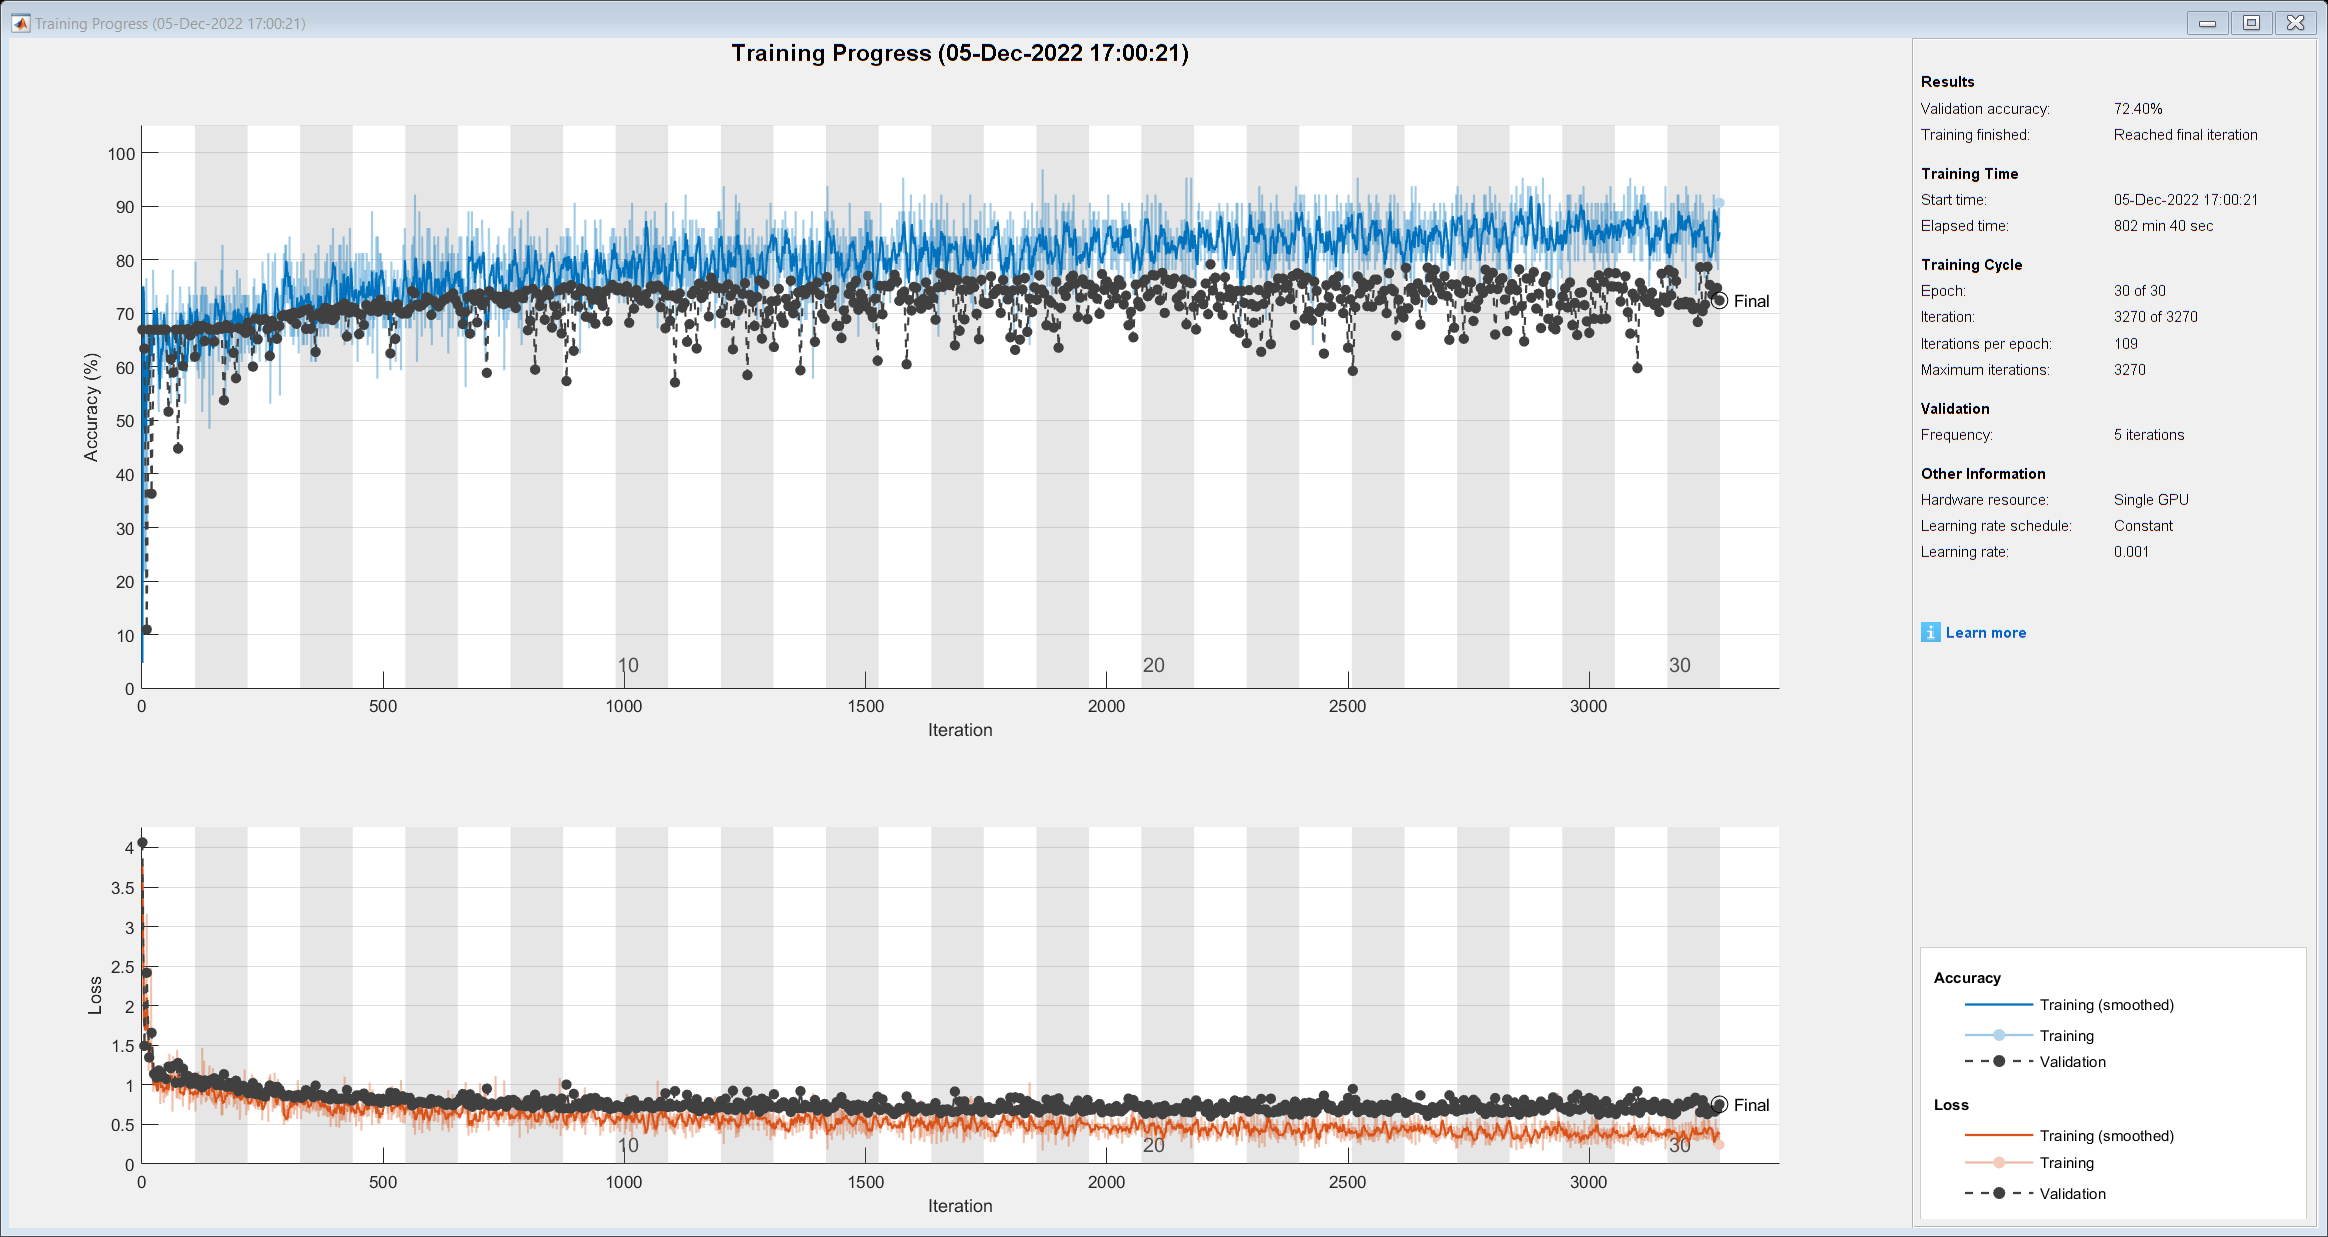

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

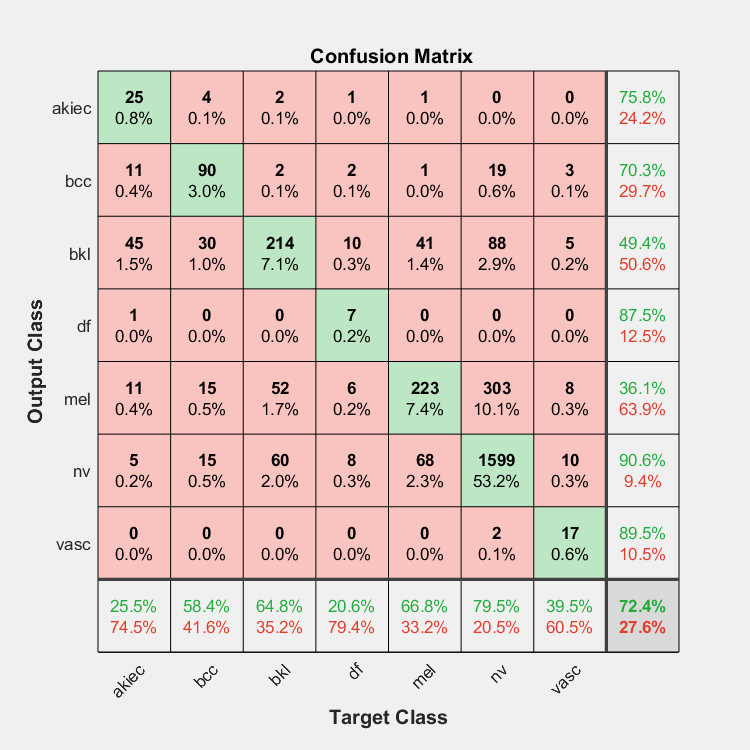

yPred = classify(net, imdsValidation);
yTest = imdsValidation.Labels;
plotconfusion(yTest, yPred)

figure
cm = confusionchart(yTest, yPred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties


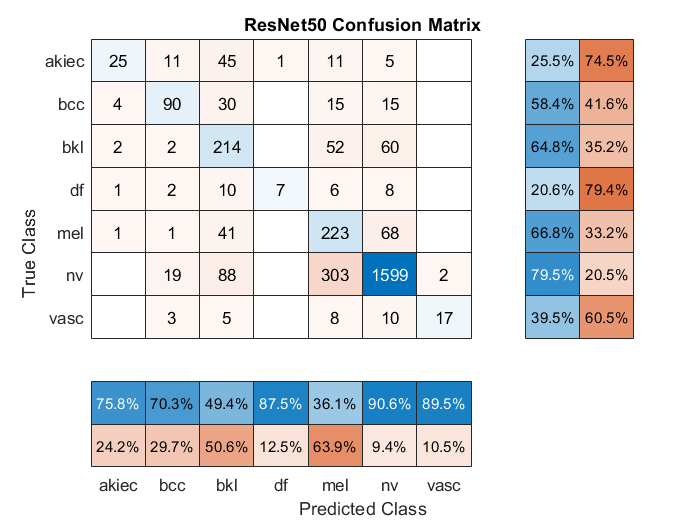

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'VGG19 Confusion Matrix';